# Lab Week 7

## FIR vs IIR for the same lowpass design problem

1) Compare FIR and IIR designs for the same practical spec

2) Show that the tool gives coefficients, but the engineer chooses trade-offs

3) Examine magnitude, phase, group delay, and rough computational cost

clear; close all; clc;

## PROBLEM 1

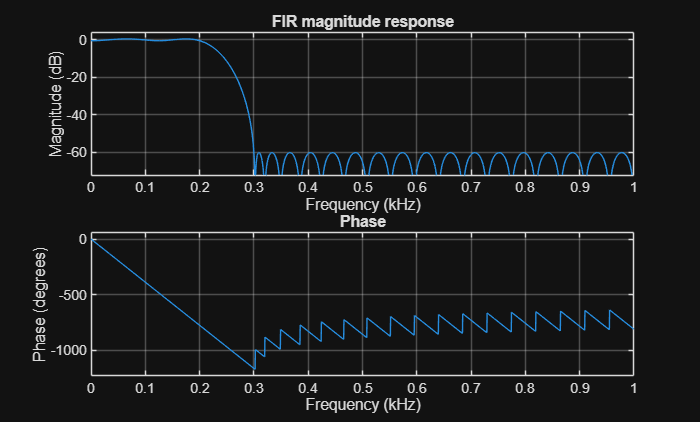

% "Design a lowpass filter for a 2 kHz-sampled signal.
% Keep 0-200 Hz with little distortion.
% Strongly suppress components above 300 Hz."

Fs = 2000;              % Hz
Fp = 200;               % passband edge (Hz)
Fst = 300;              % stopband edge (Hz)
Ap = 1;                 % passband ripple (dB)
Ast = 60;               % stopband attenuation (dB)

%% Build a test signal
t = 0:1/Fs:2;
x = 0.9*sin(2*pi*80*t) + 0.7*sin(2*pi*180*t) + 0.5*sin(2*pi*450*t) ...
    + 0.15*randn(size(t));

%% FIR design: linear-phase equiripple
dFIR = designfilt('lowpassfir', ...
    'PassbandFrequency', Fp, ...
    'StopbandFrequency', Fst, ...
    'PassbandRipple', Ap, ...
    'StopbandAttenuation', Ast, ...
    'SampleRate', Fs, ...
    'DesignMethod', 'equiripple'); % EQUIRIPPLE

%% IIR design: elliptic (small order, nonlinear phase)
dIIR = designfilt('lowpassiir', ...
    'PassbandFrequency', Fp, ...
    'StopbandFrequency', Fst, ...
    'PassbandRipple', Ap, ...
    'StopbandAttenuation', Ast, ...
    'SampleRate', Fs, ...
    'DesignMethod', 'ellip'); % ELLIP

%% FIR Magnitude responses
figure('Name','Magnitude responses');
freqz(dFIR, 2048, Fs);
title('FIR magnitude response');

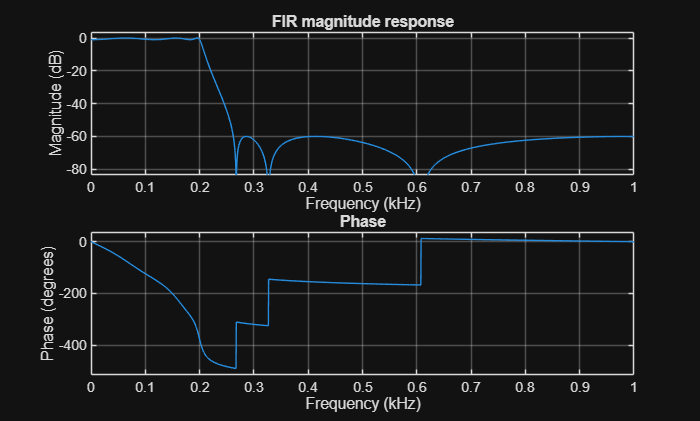

%% IIR Magnitude responses
figure('Name','Magnitude responses');
freqz(dIIR, 2048, Fs);
title('FIR magnitude response');

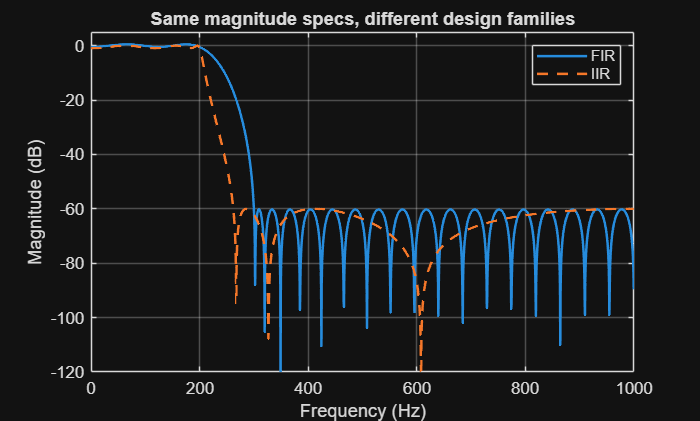

%% Compare both on one plot
% Compute the Frequency Response 
% (use freqz, with 2048 points, provide sample Frequency)

% Use [b,a] = tf(dFIR) or [b,a] = tf(dIIR) to get the LCCDE filter coefficients.
[bFIR, aFIR] = tf(dFIR) ;
[bIIR, aIIR] = tf(dIIR) ;

%% Filter the signal (use the filter command)
yFIR = filter(bFIR, aFIR, x);
yIIR = filter(bIIR, aIIR, x);

%% Frequency domain of the Transfer Function
[HFIR, f] = freqz(bFIR, aFIR, 2048, Fs);
[HIIR, ~] = freqz(bIIR, aIIR, 2048, Fs);

figure('Name','FIR vs IIR magnitude');
plot(f, 20*log10(abs(HFIR)+eps), 'LineWidth', 1.5); hold on;
plot(f, 20*log10(abs(HIIR)+eps), '--', 'LineWidth', 1.5);
grid on;
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
legend('FIR', 'IIR');
title('Same magnitude specs, different design families');
ylim([-120 5]);

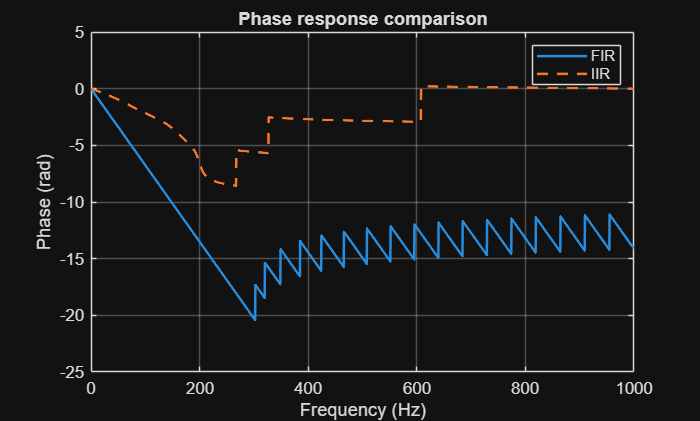

%% Phase comparison

% Phase of the transfer function in the frequency domain
phaseSpecFIR = unwrap(angle(HFIR));
phaseSpecIIR = unwrap(angle(HIIR));

figure('Name','Phase comparison');
plot(f, phaseSpecFIR, 'LineWidth', 1.5); hold on;
plot(f, phaseSpecIIR, '--', 'LineWidth', 1.5);
grid on;
xlabel('Frequency (Hz)');
ylabel('Phase (rad)');
legend('FIR', 'IIR');
title('Phase response comparison');

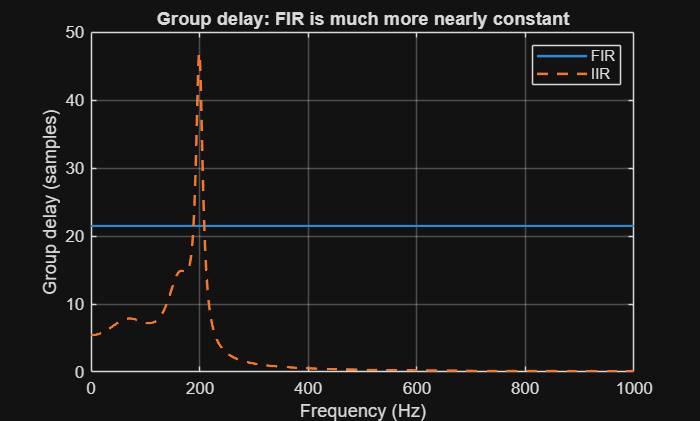

%% Group delay comparison
% Use MATLAB group delay function: grpdelay
% Use 2048 points and supply sample rate

% Frequency components delayed by a signal.
[gdFIR, fg1] = grpdelay(bFIR, aFIR, 2048, Fs) ;
[gdIIR, fg2] = grpdelay(bIIR, aIIR, 2048, Fs) ;

figure('Name','Group delay comparison');
plot(fg1, gdFIR, 'LineWidth', 1.5); hold on;
plot(fg2, gdIIR, '--', 'LineWidth', 1.5);
grid on;
xlabel('Frequency (Hz)');
ylabel('Group delay (samples)');
legend('FIR', 'IIR');
title('Group delay: FIR is much more nearly constant');

## **Visualization 1: Spectrum Before and After Filtering**

This is the clearest way to show that lowpass filtering worked.

We plot only the positive-frequency half of the FFT.

Nfft = 4096;

% Use fft to compute the spectrum now
% Use Nfft points to compute the fft
% We do not need fftshift because we take only the positive-frequency half
X    = fft(x, Nfft); % input spectrum
YFIR = fft(yFIR, Nfft); % output spectrum FIR
YIIR = fft(yIIR, Nfft); % output spectrum IIR
